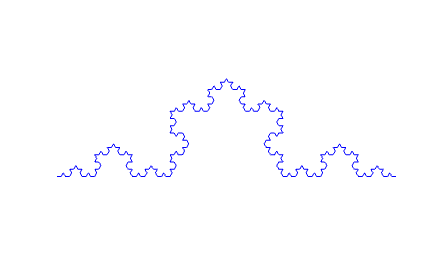

function drawKoch(n)
if nargin<1
    n=4;
end
figure; hold on; axis equal off
drawSeg([0,0],[1,0],n)
end

function drawSeg(a,b,n)
if n==0
    plot([a(1) b(1)],[a(2) b(2)],'b')
    return
end
v=(b-a)/3;
p1=a+v; p2=a+2*v;
R=[cos(pi/3) -sin(pi/3); sin(pi/3) cos(pi/3)];
p3=(p1'+R*v')';
drawSeg(a,p1,n-1)
drawSeg(p1,p3,n-1)
drawSeg(p3,p2,n-1)
drawSeg(p2,b,n-1)
end

drawKoch(4)

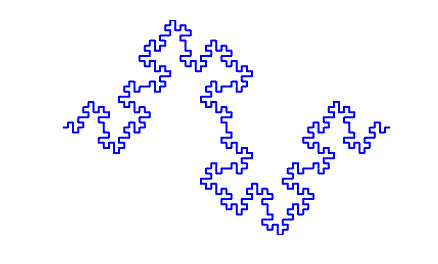

clear all
clc

function minkowski_sausage(l, iter)
segments = [0 0; l 0];
for k = 1:iter
    newSegments = [];
    for s = 1:size(segments,1)/2
        p0 = segments(2*s-1,:);
        p1 = segments(2*s,:);
        pts = generate9Points(p0, p1);
        
        for j = 1:8
            newSegments = [newSegments; pts(j,:); pts(j+1,:)];
        end
    end
    segments = newSegments;
end

x = segments(1,1);
y = segments(1,2);
for i = 2:2:size(segments,1)
    x = [x, segments(i,1)];
    y = [y, segments(i,2)];
end

figure;
plot(x, y,'b','LineWidth',1.5);
axis equal; axis off;

end

function pts = generate9Points(p0, p1)
% 输入一条线段端点 p0, p1
% 输出该线段迭代后生成的9个点

dx = p1(1) - p0(1);
dy = p1(2) - p0(2);
len = sqrt(dx^2 + dy^2);
angle = atan2(dy, dx);

unitPts = [0    0;
           1/4  0;
           1/4  1/4;
           1/2  1/4;
           1/2  0;     
           1/2 -1/4;
           3/4 -1/4;
           3/4  0;
           1    0];

% 缩放、旋转、平移到当前线段
R = [cos(angle) -sin(angle); sin(angle) cos(angle)];
pts = (R * (unitPts'*len))';
pts(:,1) = pts(:,1) + p0(1);
pts(:,2) = pts(:,2) + p0(2);
end

figure;
minkowski_sausage(1, 3)  